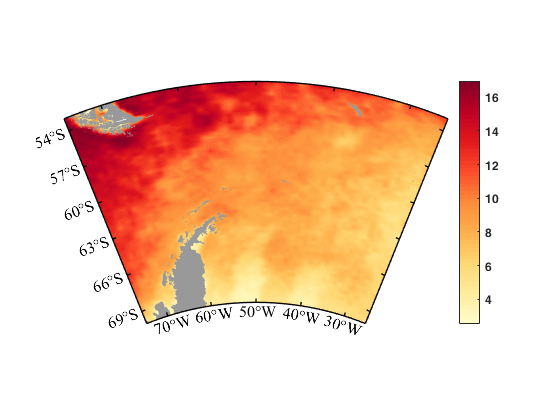

clc;clear;clf;
load ../data/ExGAN0.001.mat
sst=squeeze(data(1,:,:));

% Define longitude and latitude ranges
lon_range = [-75, -25];
lat_range = [-70, -53];

% Create new figure and axes

m_proj('lambert', 'lon', lon_range, 'lat', lat_range);



% Plot temperature data as a contour plot
% lon -> len of lat;  lat -> len of lon
lon = linspace(lon_range(1), lon_range(2), size(sst, 2));
lat = linspace(lat_range(1), lat_range(2), size(sst, 1));
[x, y]=meshgrid(lon,lat);

m_pcolor(x,y,sst);
shading interp
hold on
m_gshhs_i('patch', [0.6  0.6  0.6],'edgecolor','none');%[0.93 0.9 0.85]
% m_coast('color', 'k');
brighten(.5);
m_grid('linest','none','Linewidth',1,'fontsize',12,'FontName','Times New Roman');
load my_color2
colormap(addcolorplus(277))
% colormap(my_color2)
% Add colorbar
colorbar;